# Taula comparativa ordres

#### Mèdodes: Euler, Euler millorat, Euler modificat, rk4, ode23

#### PVI

f = @(t,y)2*y;  % equació y'=f(t,y)
a = 0;  alpha = 0.1;    % y(a) = alpha
b = 2;  % y(b) = ...

Solució analítica

Y = @(t)exp(2*t)/10;

Euler

h = 0.5;
[t, YE] = Euler(f, a, b, h, alpha);

w =           0.1


Euler Mill

[t, YEMill] = EulerMill(f, a, b, h, alpha);

w =           0.1


Euler Mod

[t, YEMod] = EulerMod(f, a, b, h, alpha);

w =           0.1


RK 4

[t, YERK4] = RK4(f, a, b, h, alpha);

w =           0.1


RK 23 (ode)

tspan = [0 2];
y0 = 0.1;
[t1, y1] = ode23(@(t,y) 2*t, tspan, y0);

RK 45 (ode)

[t2, y2] = ode45(@(t,y) 2*t, tspan, y0);

#### Comparativa erros absoluts

Els ode no están perque poden tenir tamany diferent

R = [t; YE; YEMill; YEMod,; YERK4; Y(t)]

R =             0          0.5            1          1.5            2
          0.1          0.2          0.4          0.8          1.6
          0.1         0.25        0.625       1.5625       3.9062
          0.1         0.25        0.625       1.5625       3.9062
          0.1      0.27083      0.73351       1.9866       5.3803
          0.1      0.27183      0.73891       2.0086       5.4598


P = Y(t); format shortG
R = [t; abs(YE-P); abs(YEMill-P); abs(YEMod-P); abs(YERK4-P)]'

R =             0            0            0            0            0
          0.5     0.071828     0.021828     0.021828   0.00099485
            1      0.33891      0.11391      0.11391    0.0053987
          1.5       1.2086      0.44605      0.44605     0.021972
            2       3.8598       1.5536       1.5536     0.079491


#### Gráfica

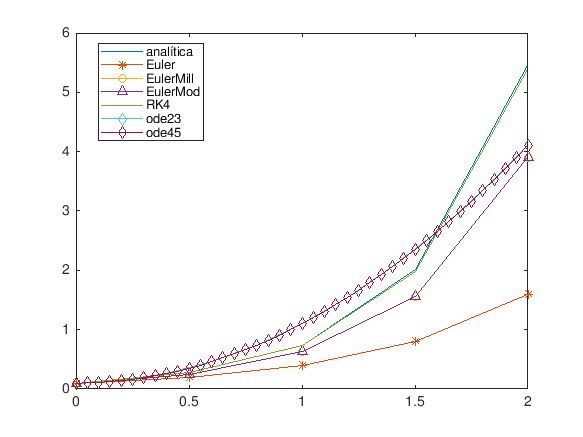

plot(t,P), hold on
plot(t, YE, '-*')
plot(t, YEMill, '-o')
plot(t, YEMod, '-^')
plot(t, YERK4)
plot(t1, y1, '-d', t2, y2, '-d')
hold off
legend('analítica', 'Euler', 'EulerMill', 'EulerMod', 'RK4', 'ode23', 'ode45', 'location', 'best')